## XROMM Automation Tutorial

The XROMM community continues to grow rapidly, as does the use of XROMM data. Concurrently, the scientific community has adopted higher standards of data reproducibility and transparency of analysis; more often than not, researchers are required to submit both their data and code alongside a manuscript.

The XROMM_MayaTools shelf, the standard toolbox for XROMM data processing, is powerful and user-friendly but is not ideal for the programmatic automation of data analysis. Thus, the motivation for the performing these operations outside of Maya is to increase **reproducibility**, **transparency**, and **ease of batch processing. **

This script will walk you through how to replicate several operations typically performed manually in Maya with a set of MATLAB functions.

Specifically, it will demonstrate how to:

- Transform 3D points from XMALab into 'Anatomical space'. *In Maya: oRel of xyz point/s relative to an ACS (anatomical coordinate system) parented to bone model.*

- Compute JCS rotations and translations. *In Maya: oRel of proximal and distal ACSs parented to bone models.*

- Batch process multiple trials. *In Maya: Concatenate all trials into a single CSV, re-run MayaTools functions.*

This script will use the standard Pig tutorial dataset. ([xmaportal.org/sandbox/](http://xmaportal.org/sandbox/larequest.php?request=explorePublicStudy&StudyID=49&instit=SANDBOX1)).

Let's go!

[Written by J.D. Laurence-Chasen, 2021]

### 1. Setup

First, let's do a quick check to make sure the functions are properly downloaded.

% Check if RBT import function is there
chk = exist('import_rbt.m','file');

if chk == 2 % file exists
    disp('Nice! Found the import function. You''re good to go.')
else
    disp('Uh oh...can''t find it. Make sure functions have been downloaded and added to your MATLAB path')
end

Nice! Found the import function. You're good to go.


Once you've got your functions downloaded, let's set our working directory and check the tutorial data.

% Set working directory
cd('C:\Users\jdlc7\Documents\Code\xromm-tools\MATLAB\example-data') % CHANGE TO MATCH YOUR PATH

Check to make sure the data are there. 

dir % list current folder contents

.                    
..                   
3dpts.csv            
Cranium_acs_tm.csv   
Mandible_acs_tm.csv  
acs_template.mb      
batch                
rbt.csv              




You should see a **4 CSV files**, and a **Maya (.mb)** file. Two of the CSVs are data exported from XMALab, and the other two are the  ACS positions (right temporomandibular joint) exported from that Maya file following the `get-acs-position.md` instructions.

**Whenever you want to use your own data, you will need to follow those instructions and export ACS positions prior to running the **`xromm-tools`** functions!**

### 2. Import rigid body transformations

Now, let's import the 3D data into MATLAB.

First, we'll create a variable that's the names of the rigid bodies we have in the RBT file. It will help you keep track. 

rbnames = {'Mandible' 'Cranium'}; % this is the order of the RBTs in the rbt.csv file

The tutorial RBTs (Mandible and Cranium) have been exported from XMALab in a "Combined" file. If you export your RBTs as single files--which is totally fine--be sure to have informative and consistent names across trials.)

Now let's define index variables that will help us extract specific RBTs from a single variable.

mandible_idx = strcmp(rbnames,'Mandible'); % will equal 1, telling us mandible rbt is first in rbt.csv
cranium_idx = strcmp(rbnames,'Cranium'); % will equal 2; cranium/skull rbt is second in rbt.csv
n_rbs = length(rbnames); % for initalizing loops later on

% Note: using strcmp() is better practice than simply setting mandible_idx
% = 1; since if you ever have a different order, you can just change the
% rbnames variable, and the rest will automatically reflect that change

**Now let's actually do the import!**

`import_rbt` reads the rigid body tranformation csv file. RBTs are just expanded 4x4 transformation matrices for every frame of video, so the function also reformats the file to be dimensions: [4 x 4 x n_frames x n_rigidbodies], to make the subsequent matrix multiplication easier. Again, if you have exported your RBTs as single files, you will need to call `import_rbt` for each file--see commented out code. 

rbts = import_rbt('rbt.csv'); % import rbt/s...it's that easy!

% % Example with RBTs in separate files
% rbts = [];
% for rb = 1:n_rbs
%     filename = [rbnames{rb} '.csv'];
%     tmp_rbt = import_rbt(filename);
%     rbts(:,:,:,rb) = tmp_rbt;
% end

**How is the matrix of imported rbts structured?** To access the rigid body transformation (4x4 transformation matrix) of the **mandible** at frame `fr` of the data (one row of the CSV from XMALab), you'd do this:

fr = 15; % frame 15, arbitrarily
% for indexing: rbts(tm_rows, tm_cols, frame/s, rigidbody);
disp(rbts(:,:,fr,mandible_idx))

  Columns 1 through 3

    0.9314   -0.3151   -0.1823
   -0.2708   -0.9344    0.2315
   -0.2433   -0.1663   -0.9556
         0         0         0

  Column 4

   12.8696
   13.4770
    5.6102
    1.0000



### `3. Import 3D Points`

`import_xyz_points `reads the 3D points file. Nothing fancy, but it reformats the data into a 3-D matrix: `npoints x XYZpos x nframes`, to make indexing easier down the line.  

xyzpoints = import_xyz_points('3dpts.csv');

**How is the matrix of 3D points structured? **To access a single point's xyz position at frame `fr, `you'd do this:

point = 3; % arbitrarily
% for indexing: xyzpoints(point, xyz, frames)
disp(xyzpoints(point,:,fr))

   10.3043   10.1872   10.3246



### 4. Import Anatomical Coordinate Systems (ACS) positions (transformation matrices)

Next, we need to import the positions of the ACSs. Again, these have to be exported from Maya following the `get-acs-position.md` instructions. This step has already been performed for the pig dataset. 

`import_acs_rel_bone`  is essentially `import_rbt`, since they are both reading transformation matrices in the 1x16 Maya/XMALab format, but the ACS transformation matrices are static, so the format is just a 2-D, 4x4 matrix. 

acs_tms = []; % this variable will contain the transformation matrices for both mandible and cranium ACSs

for rb = 1:n_rbs
    filename = [rbnames{rb} '_acs_tm.csv'];
    tmp_acs_tm = import_acs_rel_bone(filename); % import
    acs_tms(:,:,rb) = tmp_acs_tm; % assign to variable
end

And let's print one of them, just to check!

% mandible ACS position (in 4x4 transformation matrix format), relative to the bone:
disp(acs_tms(:,:,mandible_idx))

  Columns 1 through 3

   -0.0942   -0.0801   -0.9923
    0.3665    0.9240   -0.1093
    0.9256   -0.3740   -0.0577
         0         0         0

  Column 4

   -3.9389
    1.3452
  -14.2559
    1.0000



### 5. Calculate ACS Motion

All the data are now imported! Yay! The next step is calculate ACS motion, or 'animate' the ACSs. Mathematically, that's just multiplying the bones' transformation by the ACS position. 

*For intuition: Imagine we are in Maya and you have positioned the ACS on the un-animated bone model exactly how you want it. You parent the ACS to the bone models, and then apply the rigid body transformation to the bone, animating it. It's that apply-animation step we're doing. But the mathematical output is the animated ACS's position through time, not the bone model's position.*

new_rbts = [];

for rb = 1:n_rbs
    tmp_rbt = rbts(:,:,:,rb);
    tmp_acs_tm = acs_tms(:,:,rb);
    new_rbts(:,:,:,rb) = apply_acs_tm(tmp_rbt, tmp_acs_tm);
end

### 6. Calculate Motion of 3D Points in Anatomical Space

Now the fun part. Let's transform the 3D points from arbitrary cube space into a ~meaningful~ cranial coordinate system (as defined by where the ACS was placed in Maya). Remember, a coordinate system transformation is essentially asking: What is the motion of element A relative to element B, where element B is the new coordinate system/origin.

% Syntax:
%   [rel_motion] = calculate_relative_motion(reference_element_xform, mobile_element_xform)

new_xyzpoints = [];

for rb = 1:n_rbs
    tmp_pts = calculate_relative_motion(new_rbts(:,:,:,rb), xyzpoints);
    new_xyzpoints(:,:,:,rb) = tmp_pts;
end

### 7. Quantify TMJ Motion via Joint Coordinate System

Now let's quantify motion at the TMJ using a joint coordinate system (JCS).

new_cranium_rbt = new_rbts(:,:,:,cranium_idx);
new_mandible_rbt = new_rbts(:,:,:,mandible_idx);

jcs_tm = calculate_relative_motion(new_cranium_rbt, new_mandible_rbt);

% convert to tait-bryan angles + translations, the jcs standard
jcs_data = convert_tm_to_jcs(jcs_tm);

Let's plot the results to see if things make sense.

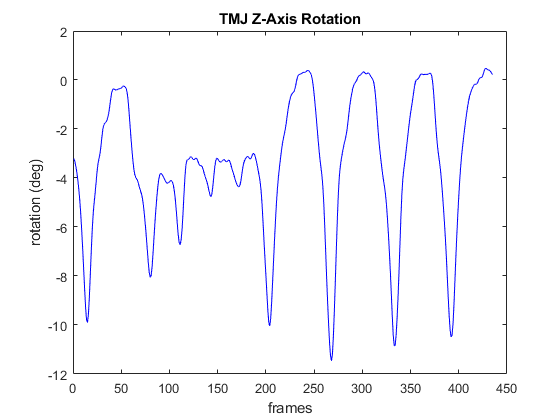

figure;
zrot = jcs_data(:,6); % z-axis rotations, always the 6th column of JCS data
plot(zrot,'b')
xlabel('frames')
ylabel('rotation (deg)')
title('TMJ Z-Axis Rotation')

### 5. Automate Calculations Across Multiple Trials

Now let's do an example of how to automate this across multiple trials. Let's first duplicate the files with new names so we have some data to work with.

% make folder for batch demo
mkdir 'batch'


% create a "trial 01" and "trial 02" by copying original files into new
% folder with new names
copyfile('3dpts.csv','batch\3dpts_trial01.csv');
copyfile('3dpts.csv','batch\3dpts_trial02.csv');

copyfile('rbt.csv','batch\rbt_trial01.csv');
copyfile('rbt.csv','batch\rbt_trial02.csv');

Now in this section, we'll repeat all of the previous steps, iterating through the two trials, but generate an output variable `jcs_data `that is a cell array, where each cell contains the jcs data from a single trial

mandible_idx = strcmp(rbnames,'Mandible'); 
cranium_idx = strcmp(rbnames,'Cranium'); 
n_rbs = length(rbnames);

% import ACS positions
acs_tms = []; 
for rb = 1:n_rbs
    filename = [rbnames{rb} '_acs_tm.csv'];
    tmp_acs_tm = import_acs_rel_bone(filename); % import
    acs_tms(:,:,rb) = tmp_acs_tm; % assign to variable
end

% Set trialnames to pull
trialnames = {'trial01' 'trial02'};
n_trials = length(trialnames);

% initialize variables as cell arrays 
xyzpoints_bytrial = cell(n_trials,1); % this will be XYZ points in anatomical coordinate systems
jcs_data_bytrial = cell(n_trials,1); % this will be TMJ JCS data

% Loop through trials
for tr = 1:n_trials
    
    % Having consistent filename structure/prefixes is
    % essential for automating across trials
    rbt_filename = ['batch\rbt_' trialnames{tr} '.csv'];
    xyz_filename = ['batch\3dpts_' trialnames{tr} '.csv'];
    
    rbts = import_rbt(rbt_filename);
    xyzpoints = import_xyz_points(xyz_filename);  
    
    % calculate ACS motion
    new_rbts = [];
    for rb = 1:n_rbs
        tmp_rbt = rbts(:,:,:,rb);
        tmp_acs_tm = acs_tms(:,:,rb);
        new_rbts(:,:,:,rb) = apply_acs_tm(tmp_rbt, tmp_acs_tm);
    end
    
    % transform xyz points into anatomical coordinate systems
    new_xyzpoints = [];
    for rb = 1:n_rbs
        tmp_pts = calculate_relative_motion(new_rbts(:,:,:,rb), xyzpoints);
        new_xyzpoints(:,:,:,rb) = tmp_pts;
    end
    
    % Save
    xyzpoints_bytrial{tr} = new_xyzpoints;
    
    % calculate tmj JCS 
    new_cranium_rbt = new_rbts(:,:,:,cranium_idx);
    new_mandible_rbt = new_rbts(:,:,:,mandible_idx);
    jcs_tm = calculate_relative_motion(new_cranium_rbt, new_mandible_rbt);
    % convert to tait-bryan angles + translations, the jcs standard
    jcs_data = convert_tm_to_jcs(jcs_tm);
    % Save
    jcs_data_bytrial{tr} = jcs_data;
end

And that's it! Now let's plot the results (don't worry, they should look the same)

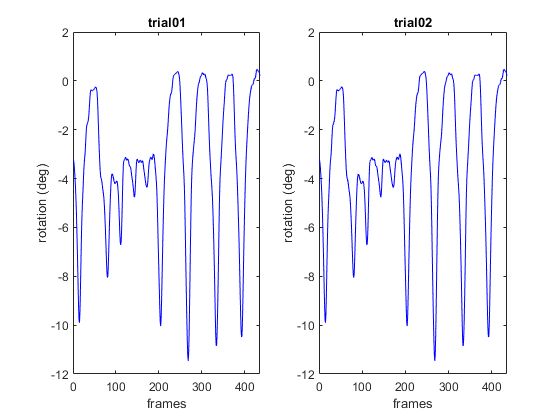

figure;
for tr = 1:n_trials
    subplot(1,n_trials,tr)
    zrot = jcs_data_bytrial{tr}(:,6); % z-axis rotations
    plot(zrot,'b')
    xlabel('frames')
    ylabel('rotation (deg)')
    title(trialnames{tr})
end